%% single cell senario
dt = 0.1;
T = 100000;
eps = 1e-6;
eqn_num = 10;
num_simulations = 25;
initPos = randi([0, 1], 1, eqn_num);%生成行向量
T_pre = 24 * 30;
T_sim = 72 * 10;
T_show = 72;
L_pre = floor(T_pre / dt);
L_sim = floor(T_sim / dt);
L_show = floor(T_show / dt);

## 51 parameters

cyc_c=1;
S1=1.45;
S3=1.45;
S2=0.48;
S4=0.48;
S5=1.63;
S6=0.47;
%S6=0.8
r=4;
R1=1.02;
R2=1.02;
R3=0.89;
a=1;
A1=0.45;
A2=0.45;
A3=0.8;
B1=0;
B2=0;
B3=0.6;
V1=1.45;
V2=1.45;
V3=1.63;
V4=1.63;
T1=1.73;
T2=0.72;
T3=1.63;
T4=0.52;
K1=2;
K2=2;
K3=2;
K4=2;
D1=0.94;
D3=0.94;
D2=0.44;
D4=0.44;
D5=0.44;
D6=0.29;
D7=0.54;
D8=0.6;
D9=0.6;
D10=0.3;
L1=0.3;
L3=0.3;
L2=0.2;
L4=0.2;
L5=0.2;
L6=0.2;
L7=0.13;
L8=0.2;
L9=0.2;
L10=0.2;
D0=0.012;
C1=0;C2=0;C3=0;

## 10 variables

Per_m = zeros(100000,1);
Per_c = zeros(100000,1);
Tim_m = zeros(100000,1);
Tim_c = zeros(100000,1);
PT_c = zeros(100000,1);
PT_n = zeros(100000,1);
Clk_m = zeros(100000,1);
Clk_c = zeros(100000,1);
CC_c = zeros(100000,1);
CC_n = zeros(100000,1);

## interlocked

% initial condition
Per_m(1)=3;
Tim_m(1)=0;
PT_c(1)=0;
PT_n(1)=0;
Clk_m(1)=2;
Clk_c(1)=0;
CC_c(1)=0.05;
CC_n(1)=0.05;

% iteration
for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = C3+S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end

time_steps = zeros(100000,1);
for t=2:T
    time_steps(t,1)=t;
end

## Find peak

[pks, locs] = findpeaks(Per_m(end-L_show+1:end),time_steps(1:L_show));

t0=locs(1);
MPer_m=pks(1);

period=mean(diff(locs))*0.1;

Peaks={};
mols={'Per_m','Per_c','Tim_m','Tim_c','PT_c','PT_n',...
    'Clk_m','Clk_c','CC_c','CC_n'};

for i=1:length(mols)
    mol=eval(mols{i});
    [pks_i,locs_i]=findpeaks(mol(end-L_show+1:end),time_steps(1:L_show));
    firstPeakAfterT0 = locs_i(find(locs_i >= t0, 1, 'first'));
    d = firstPeakAfterT0 - t0;
    phase = d/period;
    Peaks{i} = struct('mole', mols{i}, 'FirstPeak', firstPeakAfterT0, 'Distance', d, 'Phase', phase);
end




## Visualize-1

Tplot=3000;
figure;

subplot(2,5,1);
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'r', 'DisplayName', 'Per_m');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,2);
plot(time_steps(1:L_show)*dt, Per_c(end-L_show+1:end), 'm', 'DisplayName', 'Per_c');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,3);
plot(time_steps(1:L_show)*dt, Tim_m(end-L_show+1:end), 'b', 'DisplayName', 'Tim_m');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,4);
plot(time_steps(1:L_show)*dt, Tim_c(end-L_show+1:end), 'c', 'DisplayName', 'Tim_c');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,5);
plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,6);
plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,7);
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end), 'k', 'DisplayName', 'Clk_m');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,8);
plot(time_steps(1:L_show)*dt, Clk_c(end-L_show+1:end), 'Color', [0.5 0.5 0.5], 'DisplayName', 'Clk_c');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,9);
plot(time_steps(1:L_show)*dt, CC_c(end-L_show+1:end), 'Color', [1 0.5 0.1], 'DisplayName', 'CC_c');
legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

subplot(2,5,10);
plot(time_steps(1:L_show)*dt, CC_n(end-L_show+1:end), 'Color', [0.8 0.2 0.4], 'DisplayName', 'CC_n');
legend('Location', 'northeast');
xlabel('Time (hr)');Tplot

Tplot = 3000

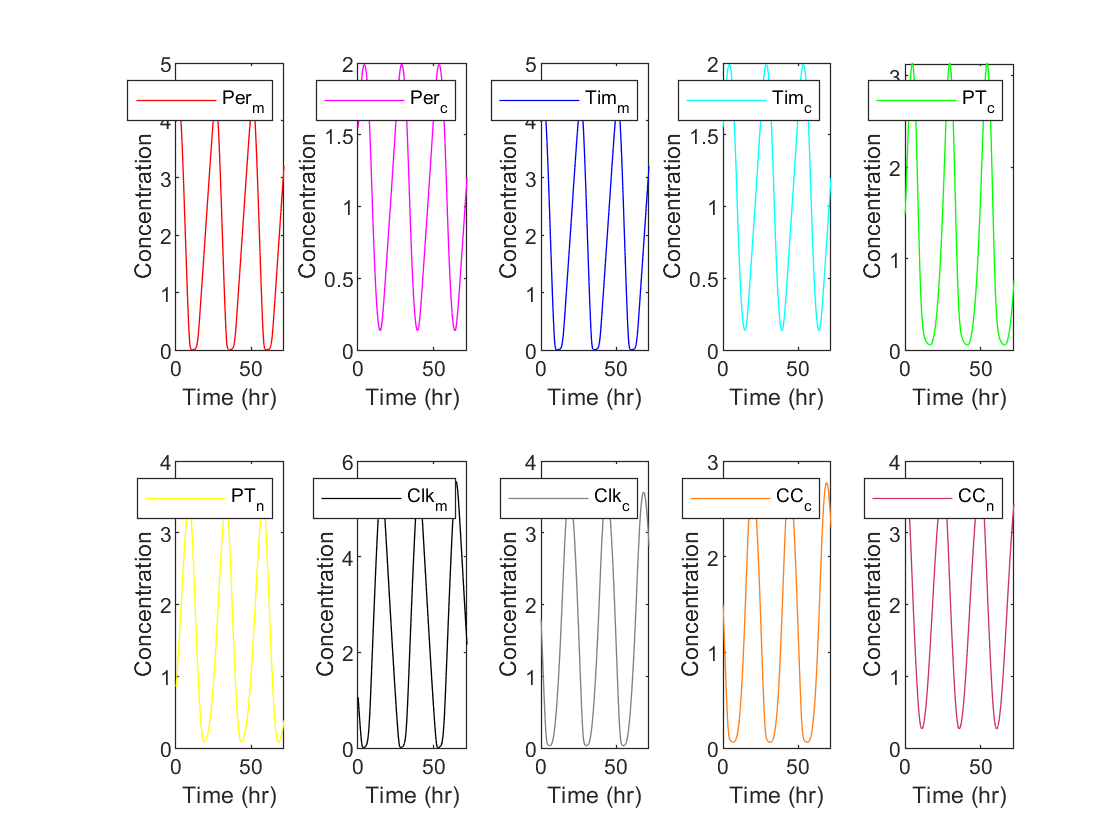

ylabel('Concentration');

## Visualize-2

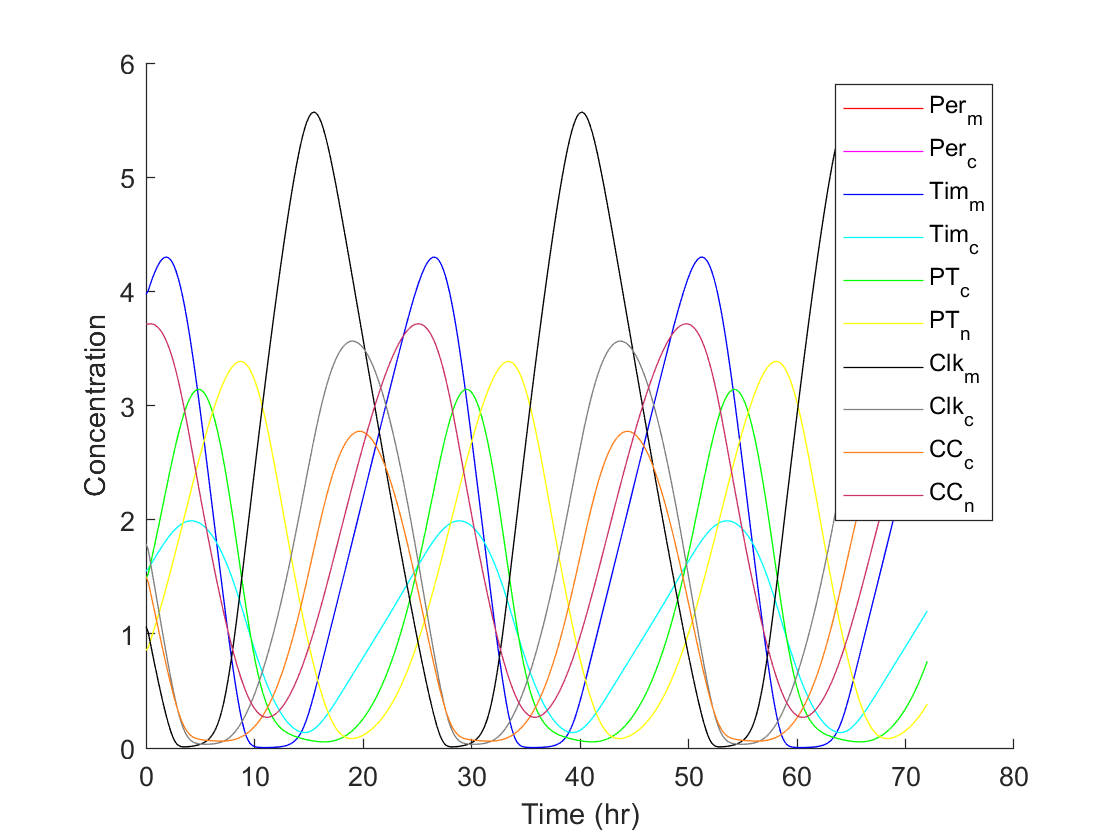

figure;

hold on;

plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Per_c(end-L_show+1:end), 'm', 'DisplayName', 'Per_c');
plot(time_steps(1:L_show)*dt, Tim_m(end-L_show+1:end), 'b', 'DisplayName', 'Tim_m');
plot(time_steps(1:L_show)*dt, Tim_c(end-L_show+1:end), 'c', 'DisplayName', 'Tim_c');
plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end), 'k', 'DisplayName', 'Clk_m');
plot(time_steps(1:L_show)*dt, Clk_c(end-L_show+1:end), 'Color', [0.5 0.5 0.5], 'DisplayName', 'Clk_c');
plot(time_steps(1:L_show)*dt, CC_c(end-L_show+1:end), 'Color', [1 0.5 0.1], 'DisplayName', 'CC_c');
plot(time_steps(1:L_show)*dt, CC_n(end-L_show+1:end), 'Color', [0.8 0.2 0.4], 'DisplayName', 'CC_n');

legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

## Visualize-3

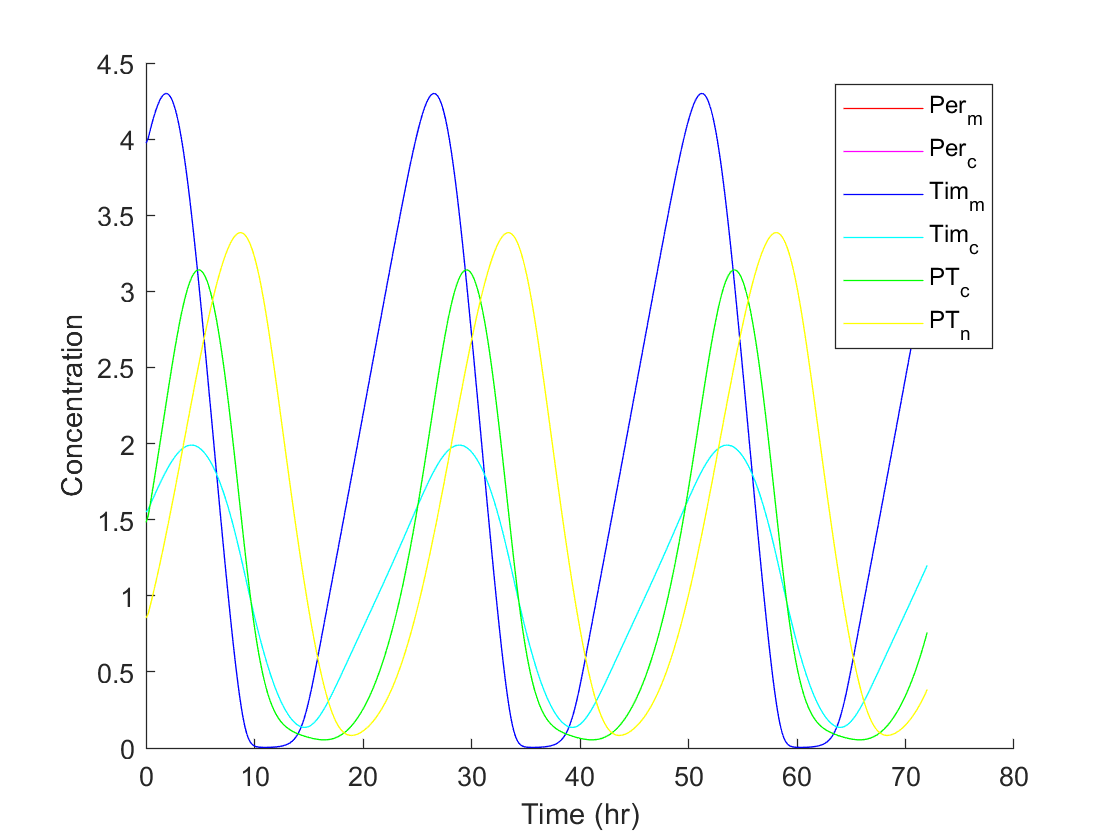

Tplot=2000;
figure;

hold on;

plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Per_c(end-L_show+1:end), 'm', 'DisplayName', 'Per_c');
plot(time_steps(1:L_show)*dt, Tim_m(end-L_show+1:end), 'b', 'DisplayName', 'Tim_m');
plot(time_steps(1:L_show)*dt, Tim_c(end-L_show+1:end), 'c', 'DisplayName', 'Tim_c');
plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');

legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

## Visualize-4

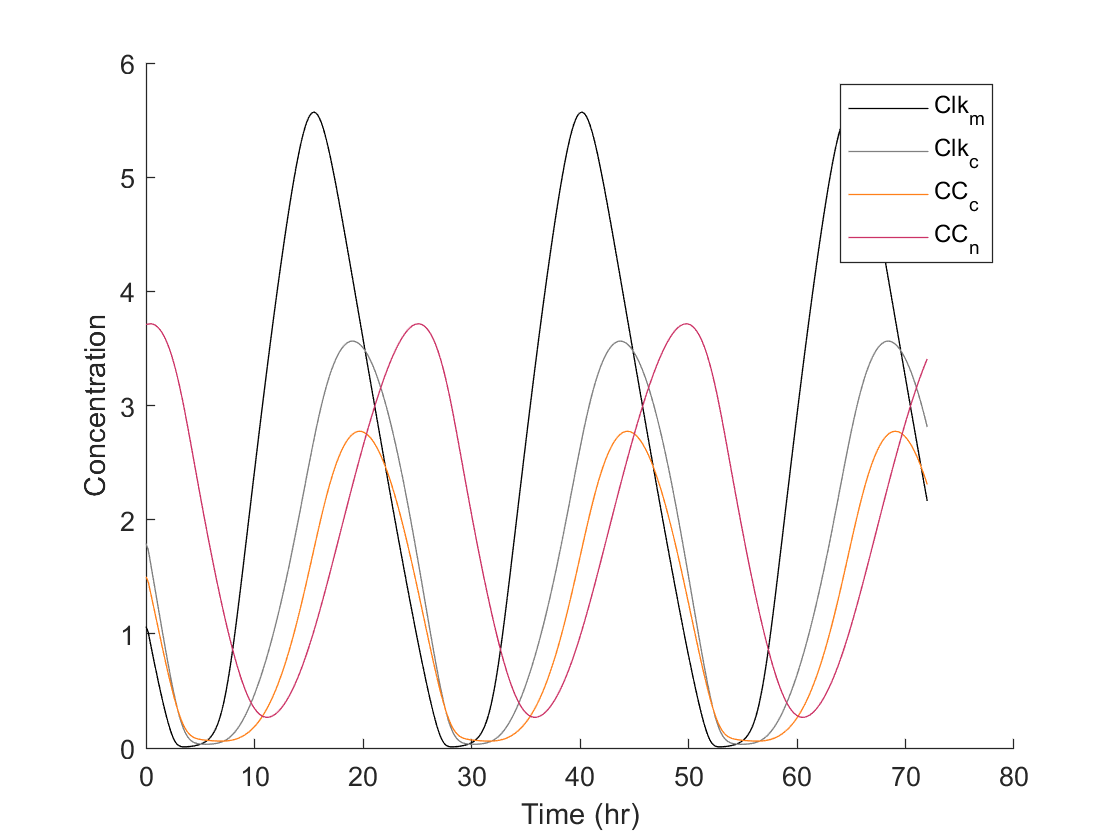

Tplot=2000;
figure;

hold on;

plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end), 'k', 'DisplayName', 'Clk_m');
plot(time_steps(1:L_show)*dt, Clk_c(end-L_show+1:end), 'Color', [0.5 0.5 0.5], 'DisplayName', 'Clk_c');
plot(time_steps(1:L_show)*dt, CC_c(end-L_show+1:end), 'Color', [1 0.5 0.1], 'DisplayName', 'CC_c');
plot(time_steps(1:L_show)*dt, CC_n(end-L_show+1:end), 'Color', [0.8 0.2 0.4], 'DisplayName', 'CC_n');

legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');

## Visualize-5

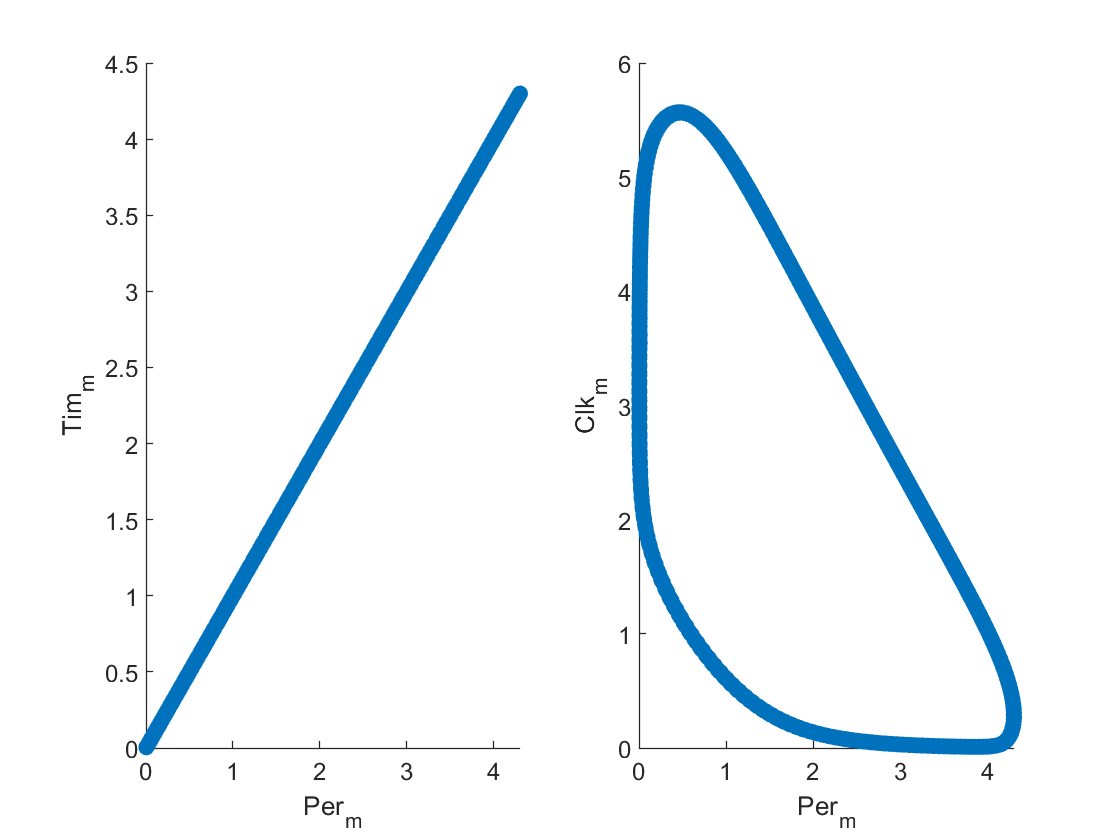

figure;
subplot(1,2,1);
scatter(Per_m(end-L_show+1:end), Tim_m(end-L_show+1:end), 'filled');
xlabel('Per_m');
ylabel('Tim_m');
subplot(1,2,2);
scatter(Per_m(900:Tplot), Clk_m(900:Tplot), 'filled');
xlabel('Per_m');
ylabel('Clk_m');

## Light Perturbation

rate_fold=[2,4,6,8,10];
color=['b','m','g','y','r'];

period=24.7

period = 24.7000

% presimulation
[~, locs] = findpeaks(-1*Per_m(1:T),time_steps(1:T));

startTime=locs(end-10);

[~, locs] = findpeaks(Per_m(end-L_show+1:end),time_steps(1:L_show));

t0=locs(1)*0.1;

D4_0=D4;
figure;
hold on;

time_steps = zeros(100000,1);
for t=2:T
    time_steps(t,1)=t;
end
    
for i=1:1:length(rate_fold)
    
    phaseshift=zeros(period*10,1);
    
    for pert=startTime:startTime+period*10
        
        for t=1:T-1 %simulation of perturb
            if t >= pert && t<pert+10
                D4=D4_0*rate_fold(i);
            end
            dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
            dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
            dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
            dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
            dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
            dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
            dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
            dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
            dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
            dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);
        
            Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
            Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
            Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
            Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
            PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
            PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
            Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
            Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
            CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
            CC_n(t+1)=CC_n(t)+dCC_ndt*dt;
        
            D4=D4_0;
        end
        [pks, locs] = findpeaks(Per_m(end-L_show+1:end),time_steps(1:L_show));
        tnew=locs(1)*0.1;
        res=tnew-t0;
        phaseshift(pert-startTime+1,1)=res;
        if  phaseshift(pert-startTime+1,1)>12
             phaseshift(pert-startTime+1,1)= phaseshift(pert-startTime+1,1)-period;
        end
    end
    
    %plot(time_steps(1:period*10,1)*dt, phaseshift(1:period*10,1), 'Color',color(i), 'DisplayName', num2str(rate_fold(i))+'-fold');
    plot(time_steps(1:period*10,1)*dt, -phaseshift(1:period*10,1), 'Color', color(i), 'DisplayName', sprintf('%d-fold', rate_fold(i)));
    hold on;

end
ylabel('Phase Shift (hr)');Tplot

Tplot = 2000

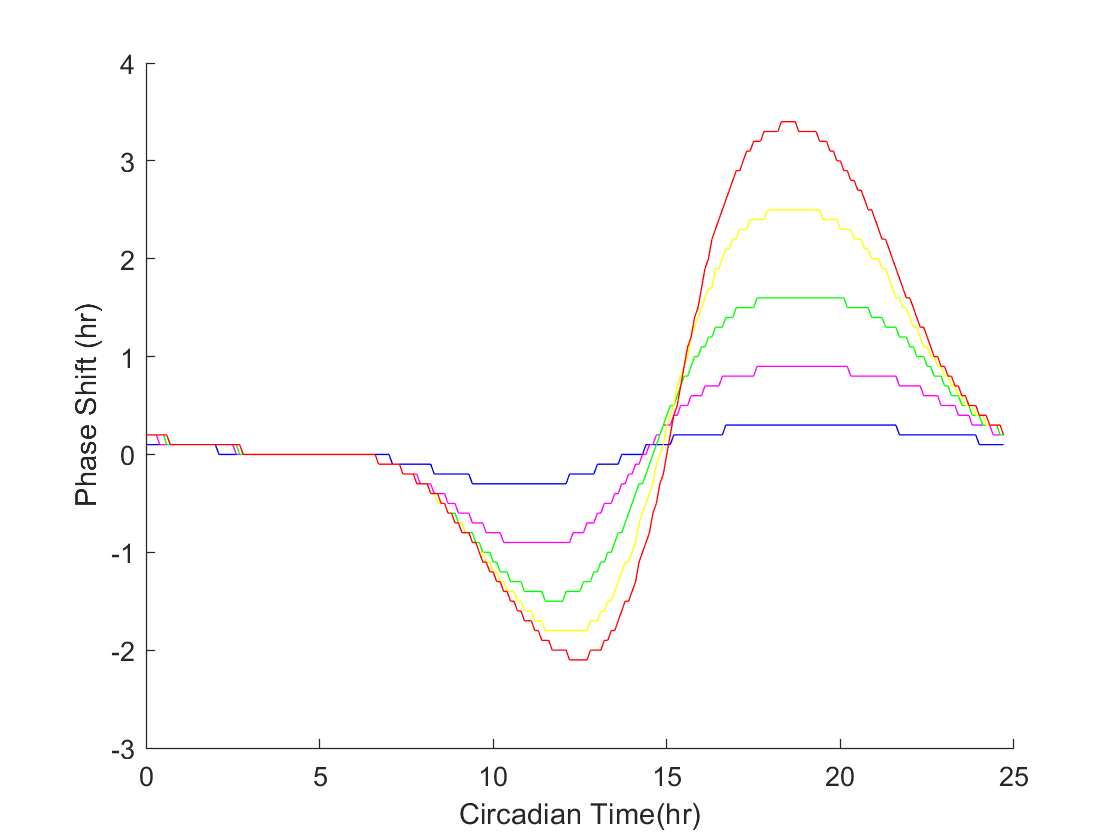

xlabel('Circadian Time(hr)');

## LD period

L_time=16;
D_time=8;
Per_m(1)=3;
Tim_m(1)=0;
PT_c(1)=0;
PT_n(1)=0;
Clk_m(1)=2;
Clk_c(1)=0;
CC_c(1)=0.05;
CC_n(1)=0.05;

flag=0

flag = 0

flag_list=zeros(100000,1);
count=0

count = 0

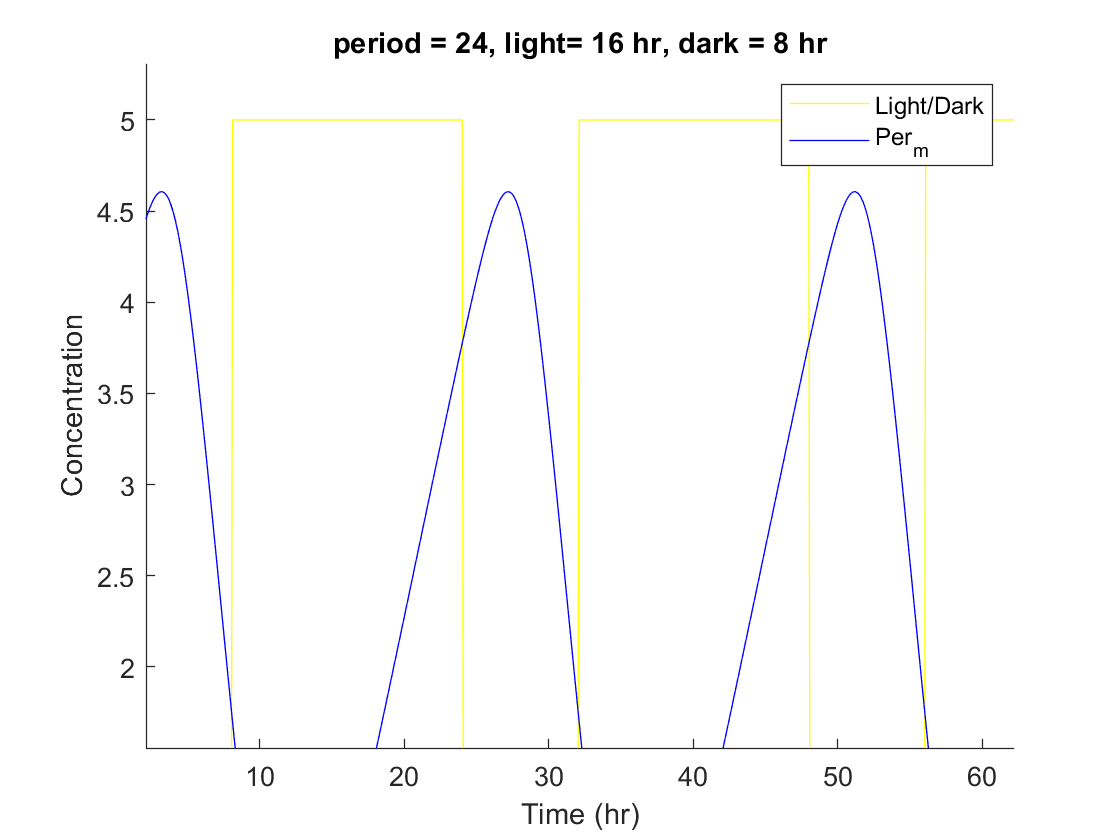

rf=2;
D4_0=D4;

% iteration
for t=1:T-1
    
    if flag==0
        if count==L_time/dt
            flag=1;
            count=0;
        end
    else
        if count==D_time/dt
            flag=0;
            count=0;
        end
    end
    
    if flag==0
        D4=D4_0*rf;
    end
    
    flag_list(t)=flag;

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = C3+S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

    D4=D4_0;
    count=count+1;
end

figure;
% f=figure;
% 
% set(f, 'Color', 'w');
% hold on;
% ax = axes('Parent', f);

hold on;


plot(time_steps(1:L_show)*dt, (1-flag_list(end-L_show+1:end))*5, 'y', 'DisplayName', 'Light/Dark');
hold on;
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'b', 'DisplayName', 'Per_m');
%plot(time_steps(1:L_show)*dt, Tim_m(end-L_show+1:end), 'b', 'DisplayName', 'Tim_m');
%plot(time_steps(1:L_show)*dt, Tim_c(end-L_show+1:end), 'c', 'DisplayName', 'Tim_c');
%plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
%plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');

legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');
% yLimits = get(ax, 'YLim');
% 
% hold on;
% for i = 1:L_show
%     if flag_list(end-L_show-1+i) == 1
%         % 蓝色背景
%         patch([(time_steps(i)-0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)-0.5)*dt], ...
%               [yLimits(1), yLimits(1), yLimits(2), yLimits(2)], ...
%               'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     else
%         % 黄色背景
%         patch([(time_steps(i)-0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)-0.5)*dt], ...
%               [yLimits(1), yLimits(1), yLimits(2), yLimits(2)], ...
%               'y', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     end
% end

%period = get_period(Per_m,length(Per_m)-L_show,dt)
[pks, locs] = findpeaks(Per_m(end-L_show+1:end),time_steps(1:L_show));


period=mean(diff(locs))*0.1;

titleStr = sprintf('period = %d h, light= %d h, dark = %d h', period, L_time, D_time);

% 设置标题
title(titleStr);

hold off;

L_time=8;
D_time=24-L_time;
Per_m(1)=3;
Tim_m(1)=0;
PT_c(1)=0;
PT_n(1)=0;
Clk_m(1)=2;
Clk_c(1)=0;
CC_c(1)=0.05;
CC_n(1)=0.05;

flag=0

flag = 0

flag_list=zeros(100000,1);
count=0

count = 0

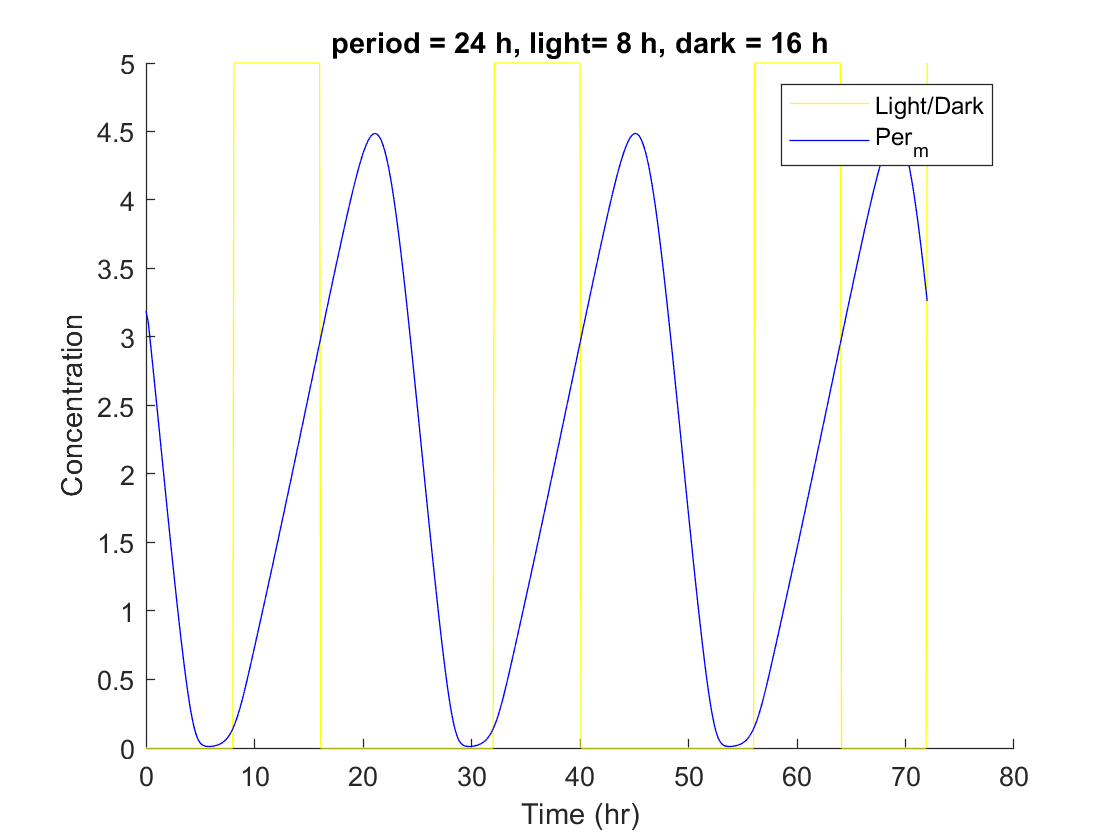

rf=2;
D4_0=D4;

% iteration
for t=1:T-1
    
    if flag==0
        if count==L_time/dt
            flag=1;
            count=0;
        end
    else
        if count==D_time/dt
            flag=0;
            count=0;
        end
    end
    
    if flag==0
        D4=D4_0*rf;
    end
    
    flag_list(t)=flag;

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = C3+S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

    D4=D4_0;
    count=count+1;
end

figure;
% f=figure;
% 
% set(f, 'Color', 'w');
% hold on;
% ax = axes('Parent', f);

hold on;


plot(time_steps(1:L_show)*dt, (1-flag_list(end-L_show+1:end))*5, 'y', 'DisplayName', 'Light/Dark');
hold on;
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'b', 'DisplayName', 'Per_m');
%plot(time_steps(1:L_show)*dt, Tim_m(end-L_show+1:end), 'b', 'DisplayName', 'Tim_m');
%plot(time_steps(1:L_show)*dt, Tim_c(end-L_show+1:end), 'c', 'DisplayName', 'Tim_c');
%plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
%plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');

legend('Location', 'northeast');
xlabel('Time (hr)');
ylabel('Concentration');
% yLimits = get(ax, 'YLim');
% 
% hold on;
% for i = 1:L_show
%     if flag_list(end-L_show-1+i) == 1
%         % 蓝色背景
%         patch([(time_steps(i)-0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)-0.5)*dt], ...
%               [yLimits(1), yLimits(1), yLimits(2), yLimits(2)], ...
%               'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     else
%         % 黄色背景
%         patch([(time_steps(i)-0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)+0.5)*dt, (time_steps(i)-0.5)*dt], ...
%               [yLimits(1), yLimits(1), yLimits(2), yLimits(2)], ...
%               'y', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
%     end
% end

%period = get_period(Per_m,length(Per_m)-L_show,dt)
[pks, locs] = findpeaks(Per_m(end-L_show+1:end),time_steps(1:L_show));


period=mean(diff(locs))*0.1;
titleStr = sprintf('period = %d h, light= %d h, dark = %d h', period, L_time, D_time);

% 设置标题
title(titleStr);


hold off;

## Visualize-6

cyc_c=1;
S1=1.45;
S3=1.45;
S2=0.48;
S4=0.48;
S5=1.63;
S6=0.47;
%S6=0.8
r=4;
R1=1.02;
R2=1.02;
R3=0.89;
a=1;
A1=0.45;
A2=0.45;
A3=0.8;
B1=0;
B2=0;
B3=0.6;
V1=1.45;
V2=1.45;
V3=1.63;
V4=1.63;
T1=1.73;
T2=0.72;
T3=1.63;
T4=0.52;
K1=2;
K2=2;
K3=2;
K4=2;
D1=0.94;
D3=0.94;
D2=0.44;
D4=0.44;
D5=0.44;
D6=0.29;
D7=0.54;
D8=0.6;
D9=0.6;
D10=0.3;
L1=0.3;
L3=0.3;
L2=0.2;
L4=0.2;
L5=0.2;
L6=0.2;
L7=0.13;
L8=0.2;
L9=0.2;
L10=0.2;
D0=0.012;
% initial condition
Per_m(1)=3;
Tim_m(1)=0;
PT_c(1)=0;
PT_n(1)=0;
Clk_m(1)=2;
Clk_c(1)=0;
CC_c(1)=0.05;
CC_n(1)=0.05;
T=100000;
% iteration
for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end
maxP= max(Per_m(end-L_show+1:end));
ref=5.52867;
% 
maxC = max(Clk_m(end-L_show+1:end));
%maxC=pks(end);

figure;

subplot(2,2,1);
hold on;
ylim([0,140]);
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end)/maxP*100, 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end)/maxC*100, 'b', 'DisplayName', 'Clk_m');
xlabel('Time (hr)');
ylabel('Relative Concentration');


S2=0;
for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end
subplot(2,2,2);
ylim([0,140]);
hold on;
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end)/maxP*100, 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end)/maxC*100, 'b', 'DisplayName', 'Clk_m');
xlabel('Time (hr)');
ylabel('Relative Concentration')

disp(max(Per_m(end-L_show+1:end))/maxP*100)

   44.5795



disp(max(Clk_m(end-L_show+1:end))/maxC*100)

   47.8700



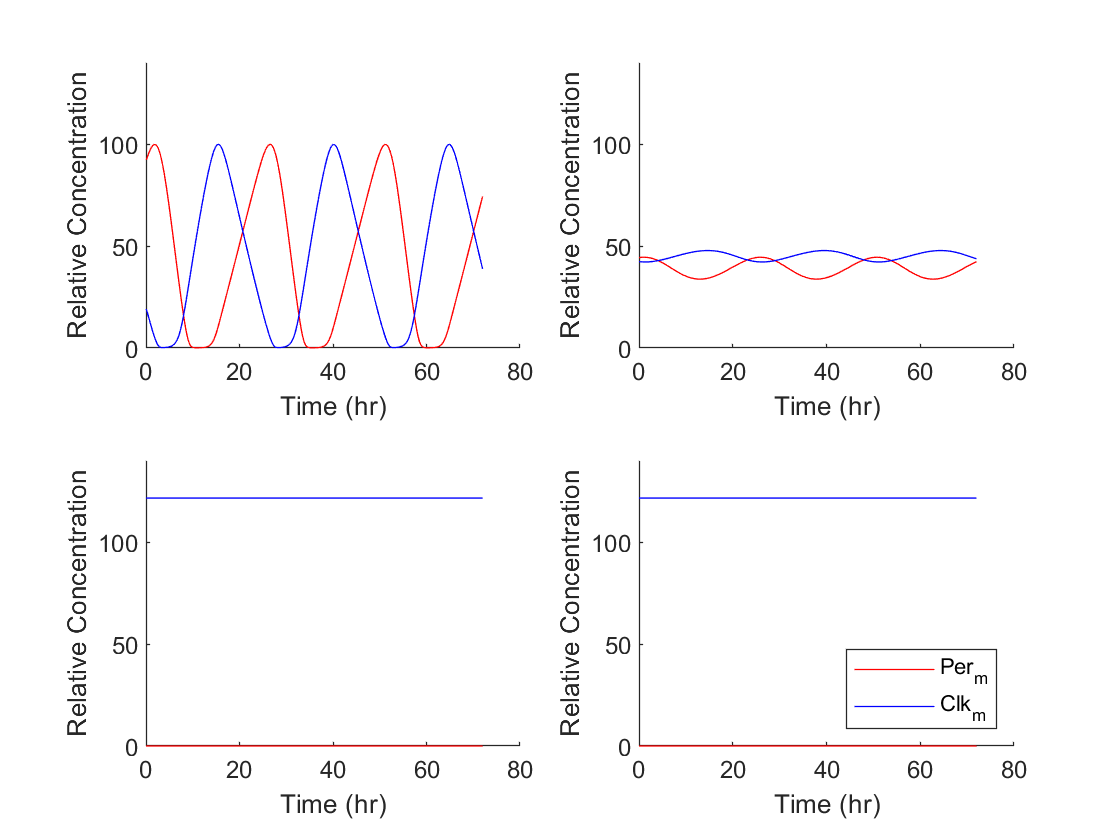



S2=0.48;

S6=0;

for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end

subplot(2,2,3);
hold on;
ylim([0,140]);
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end)/maxP*100, 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end)/maxC*100, 'b', 'DisplayName', 'Clk_m');
xlabel('Time (hr)');
ylabel('Relative Concentration');

S6=0.47;
S2=0;S6=0;
for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end
subplot(2,2,4);
hold on;
ylim([0,140]);
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end)/maxP*100, 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Clk_m(end-L_show+1:end)/maxC*100, 'b', 'DisplayName', 'Clk_m');
legend('Location', 'southeast');
xlabel('Time (hr)');
ylabel('Relative Concentration');


S2=0.48;S6=0.47;

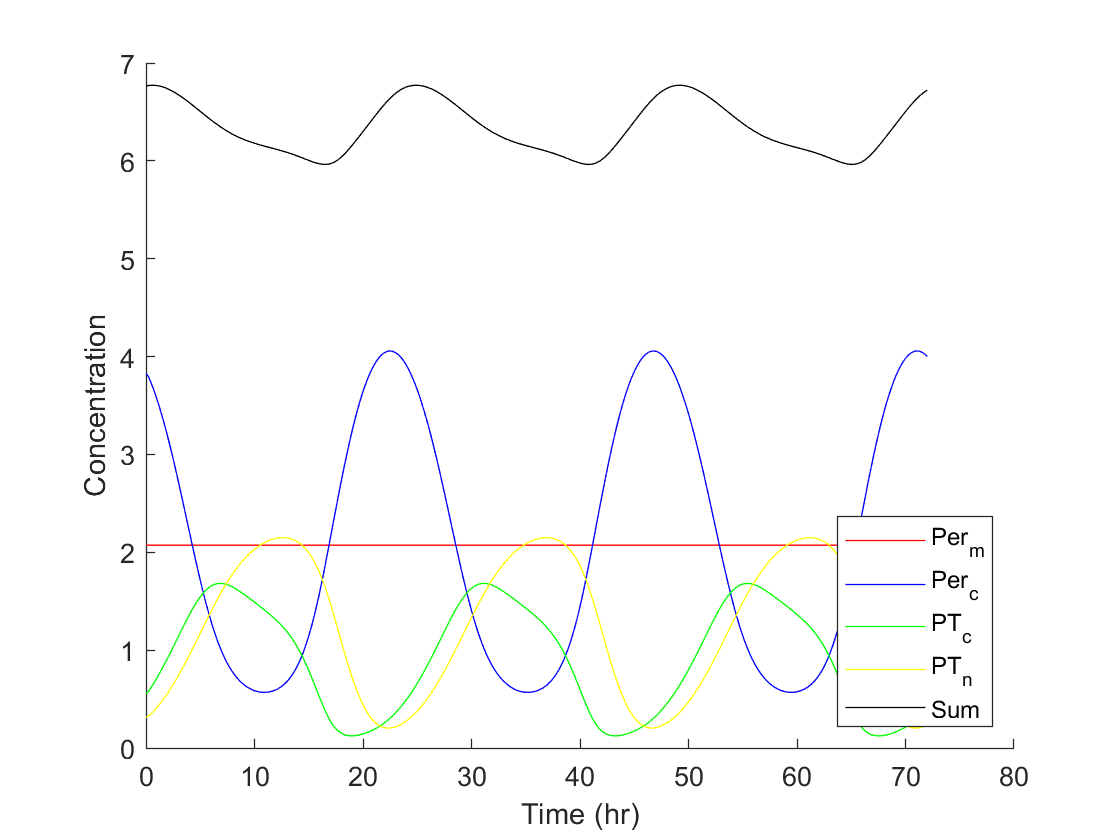

S1=0;C1=0.846;
S2=0.48;S6=0.47;
Per_m(1)=3;
Tim_m(1)=0;
PT_c(1)=0;
PT_n(1)=0;
Clk_m(1)=2;
Clk_c(1)=0;
CC_c(1)=0.05;
CC_n(1)=0.05;
T=100000;
for t=1:T-1

    dPer_mdt = C1+S1*(((CC_n(t)/A1)^a+B1)/(1+(PT_n(t)/R1)^r+(CC_n(t)/A1)^a+B1))-D1*(Per_m(t)/(L1+Per_m(t)))-D0*Per_m(t);
    dPer_cdt = S2*Per_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D2*(Per_c(t)/(L2+Per_c(t)))-D0*Per_c(t);
    dTim_mdt = C2+S3*(((CC_n(t)/A2)^a+B2)/(1+(PT_n(t)/R2)^r+(CC_n(t)/A2)^a+B2))-D3*(Tim_m(t)/(L3+Tim_m(t)))-D0*Tim_m(t);
    dTim_cdt = S4*Tim_m(t)-V1*Per_c(t)*Tim_c(t)+V2*PT_c(t)-D4*(Tim_c(t)/(L4+Tim_c(t)))-D0*Tim_c(t);
    dPT_cdt = V1*Per_c(t)*Tim_c(t)-V2*PT_c(t)-T1*(PT_c(t)/(K1+PT_c(t)))+T2*(PT_n(t)/(K2+PT_n(t)))-D5*(PT_c(t)/(L5+PT_c(t)))-D0*PT_c(t);
    dPT_ndt = T1*(PT_c(t)/(K1+PT_c(t)))-T2*(PT_n(t)/(K2+PT_n(t)))-D6*(PT_n(t)/(L6+PT_n(t)))-D0*PT_n(t);
    dClk_mdt = S5*(((PT_n(t)/A3)^a+B3)/(1+(CC_n(t)/R3)^r+(PT_n(t)/A3)^a+B3))-D7*(Clk_m(t)/(L7+Clk_m(t)))-D0*Clk_m(t);
    dClk_cdt = C3+S6*Clk_m(t)-V3*Clk_c(t)*cyc_c+V4*CC_c(t)-D8*(Clk_c(t)/(L8+Clk_c(t)))-D0*Clk_c(t);
    dCC_cdt = V3*Clk_c(t)*cyc_c-V4*CC_c(t)-T3*(CC_c(t)/(K3+CC_c(t)))+T4*(CC_n(t)/(K4+CC_n(t)))-D9*(CC_c(t)/(L9+CC_c(t)))-D0*CC_c(t);
    dCC_ndt = T3*(CC_c(t)/(K3+CC_c(t)))-T4*(CC_n(t)/(K4+CC_n(t)))-D10*(CC_n(t)/(L10+CC_n(t)))-D0*CC_n(t);

    Per_m(t+1)=Per_m(t)+dPer_mdt*dt;
    Per_c(t+1)=Per_c(t)+dPer_cdt*dt;
    Tim_m(t+1)=Tim_m(t)+dTim_mdt*dt;
    Tim_c(t+1)=Tim_c(t)+dTim_cdt*dt;
    PT_c(t+1)=PT_c(t)+dPT_cdt*dt;
    PT_n(t+1)=PT_n(t)+dPT_ndt*dt;
    Clk_m(t+1)=Clk_m(t)+dClk_mdt*dt;
    Clk_c(t+1)=Clk_c(t)+dClk_cdt*dt;
    CC_c(t+1)=CC_c(t)+dCC_cdt*dt;
    CC_n(t+1)=CC_n(t)+dCC_ndt*dt;

end
figure;
hold on;
plot(time_steps(1:L_show)*dt, Per_m(end-L_show+1:end), 'r', 'DisplayName', 'Per_m');
plot(time_steps(1:L_show)*dt, Per_c(end-L_show+1:end), 'b', 'DisplayName', 'Per_c');
plot(time_steps(1:L_show)*dt, PT_c(end-L_show+1:end), 'g', 'DisplayName', 'PT_c');
plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end), 'y', 'DisplayName', 'PT_n');
plot(time_steps(1:L_show)*dt, PT_n(end-L_show+1:end)+Per_m(end-L_show+1:end)+Per_c(end-L_show+1:end)+PT_c(end-L_show+1:end), 'k', 'DisplayName', 'Sum');
legend('Location', 'southeast');
xlabel('Time (hr)');
ylabel('Concentration')

S1=1.45;C1=0;


function period = get_period(x,thres,dt)
%GET_PERIOD 此处显示有关此函数的摘要
%   此处显示详细说明
data=x(floor(thres/dt)+1:end);
[~,pos_loc]=findpeaks(data);
period=(pos_loc(end)-pos_loc(end-1))*dt;
end


